# Drive Pattern

## FTP75 Drive Cycle

This uses Drive Cycle Source block from Powertrain Blockset.

mdl = "DrivePattern_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

DrivePattern_harness_setup

drvPtnSigBuilder = DrivePattern_InputSignalBuilder("Plot_tf",true);

% Plot_tf option is ignored by FTP75 function
% because the speed reference is produced by Drive Cycle Source block,
% not by DrivePattern_InputSignalBuilder.
inpData = FTP75(drvPtnSigBuilder);

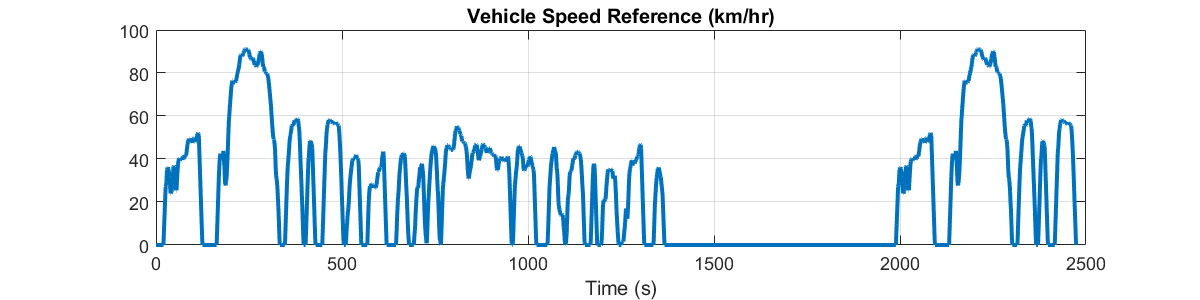

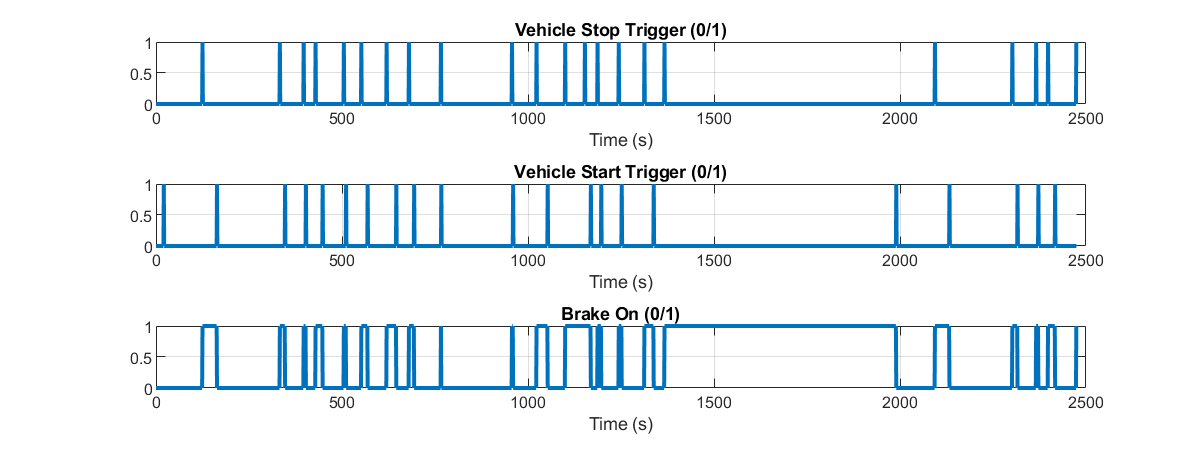

simIn = Simulink.SimulationInput(mdl);
simIn = setVariable(simIn, "drivePatternFromWorkspace", inpData.Options.useFromWorkspace);
simIn = setVariable(simIn, "drivePattern_Signals", inpData.Signals);
simIn = setVariable(simIn, "drivePattern_Bus", inpData.Bus);
simIn = setModelParameter(simIn, "StopTime",num2str(inpData.Options.StopTime_s));

simOut = sim(simIn);

DrivePattern_plot_results(simOut.logsout, "PlotExtraSignals",true);

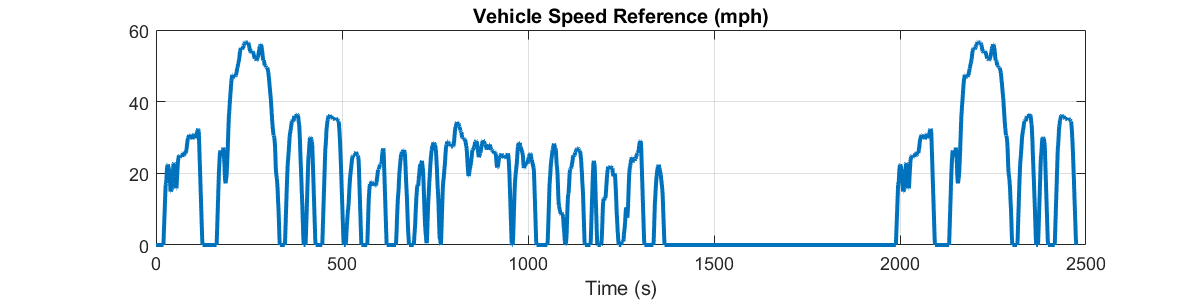

DrivePattern_plot_results(simOut.logsout, "SpeedUnit","mph");

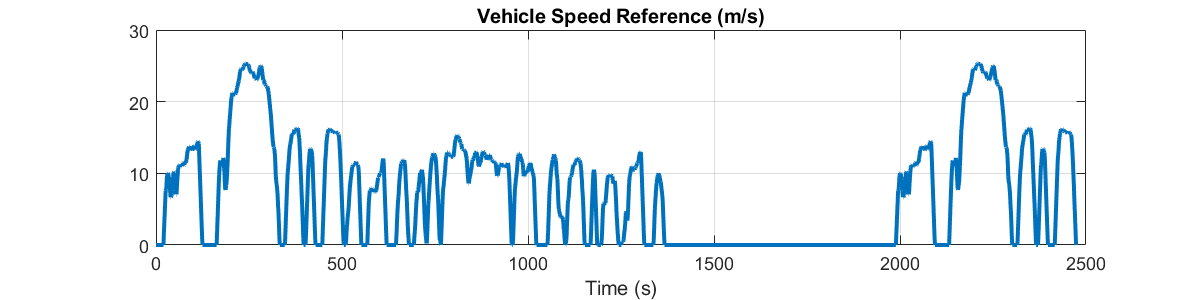

DrivePattern_plot_results(simOut.logsout, "SpeedUnit","m/s");

*Copyright 2021-2022 The MathWorks, Inc.*